# Trim, Linearise and design an **OBSERVER** for the quadcopter and **PENDULUM** model:

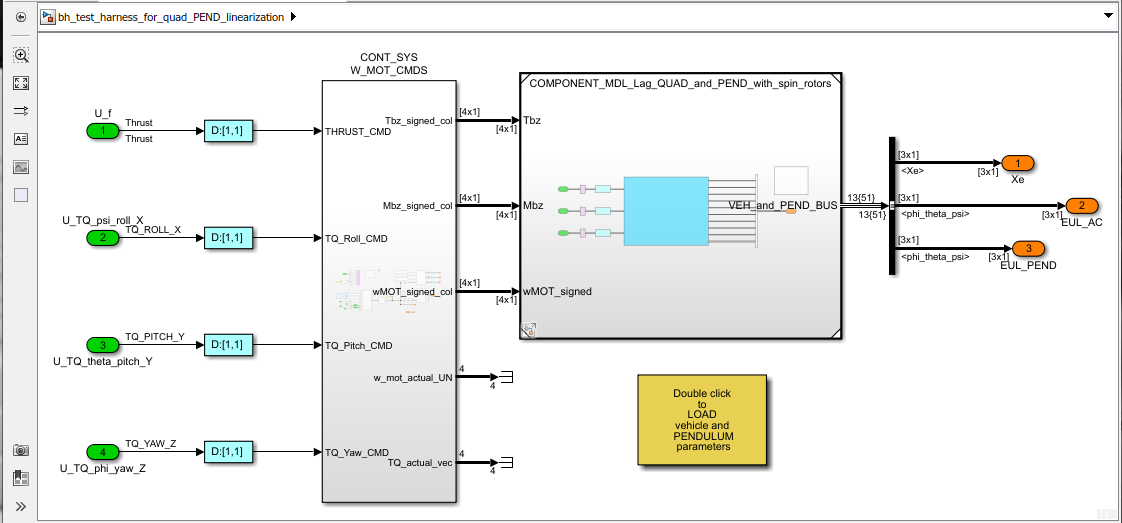

In this task we're going to linearise our **Simulink** quadcopter model. We're going to do this because we'd like to apply some "state space" control design techniques in order to design a control system for the quadcopter.  And as you know, these control techniques require a LINEAR plant model.  The workflow that we'll follow is this:

- We'll find an operating point for the pendulum. An operating point is characterized by the state(X), the input(U) and the output(Y).    We'll look specifically for an operating point that corresponds to steady state, ie: where the pendulum's state derivatives are ZERO. This is referred to as finding a **TRIMMED operating point**.

- We'll then use this TRIMMED operating point to calculate a **linearised** version of the quadcopter model.

- Finally, we'll then use this linearised model to design a full state feedback control system using the Linear Quadratic Integrator (LQI) technique.

`Bradley Horton : 08-Oct-2017, bradley.horton@mathworks.com.au`

# 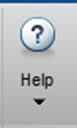 Take a moment !

If you're interested in reading about how to linearize a NON linear plant model.  Use the MATLAB HELP browser and try this simple text search

- `linearize control system`

HINT:  today we'll be using the functions:

- `operspec,   findop,   linearize`

## Load the model parameters:

bh_quad_params
bh_pend_params
bh_create_veh_and_pend_BUS

Just ensure that the the initial local Euler angles of the pendulum are ZERO:

P_pend.eul_loc_vec      =  [0,0,0]'; % rad
P_veh_no_props.eul_init = [0,0,0]'; % rad
%P_veh_no_props.Xe_init  =  0.1 + [0,0,0]'; % m

ANd echo the parameters that have been loaded into the workspace:

whos

  Name                   Size            Bytes  Class           Attributes

  PEND_BUS               1x1               310  Simulink.Bus              
  P_elec                 1x1               352  struct                    
  P_mot                  1x1              1232  struct                    
  P_mot_alone            1x1              1232  struct                    
  P_mot_vec              4x1              3584  struct                    
  P_one_prop             1x1               880  struct                    
  P_pend                 1x1               992  struct                    
  P_rot                  1x1               592  struct                    
  P_veh                  1x1              1536  struct                    
  P_veh_no_props         1x1              1536  struct                    
  VEH_AND_PEND_BUS       1x1               702  Simulink.Bus              
  XYZ_circ_mat          88x3              2112  double                    
  X_TS_OBJ              

warning('off')

## The name of the SIMULINK model that we'll linearise:

model  = 'bh_test_harness_for_quad_PEND_linearization';
set_param(0, 'CallbackTracing', 'off')
open_system(model)

## Create the operating point specification object.

opspec = operspec(model);

In our operating point specification, note the following:

- Our GREEN root level INPORT blocks are the system inputs 

- Our ORANGE root level OUTPORT blocks are the system outputs 

display(opspec)


 Operating point specification for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

States: 
----------
(1.) DOT_phi
	 spec:  dx = 0,  initial guess: 0
(2.) DOT_theta
	 spec:  dx = 0,  initial guess: 0
(3.) DOT_psi
	 spec:  dx = 0,  initial guess: 0
(4.) 

For each of our model states we can specify "desired" values for each of the following.  

- `x           :`   initial guess for state value

- `SteadyState :`   a logical indicating we are looking for a dx=0 final value

- `Min         :`   minimum bound for state value

- `Max         :`   maximum bound for state value

For our problem, we're going to look for an operating point where ALL of our states are at SteadyState (ie: dx/dt=0)

%[ opspec.States(1).SteadyState]
%[ arrayfun(@(a) (a.SteadyState), opspec.States) ].'

Our trimming function(coming up next) will then look for an operating point that satisfies this specification:

## Look for the steady state operating point.

opt           = findopOptions('DisplayReport','off');
[op,opreport] = findop(model,opspec, opt);

Review our trimmed OPERATING point and NOTE the following:

- We have indeed found a steady state operating point because the state derivatives are either zero OR very small $O(10^{-7})$

- In this trimmed pose, ALL of the system outputs are ZERO.

- To maintain this trimmed pose we need to supply an INPUT force ... which is the force to counter gravity. 

display(opreport)


 Operating point search report for the Model bh_test_harness_for_quad_PEND_linearization.
 (Time-Varying Components Evaluated at time t=0)

Operating point specifications were successfully met.
States: 
----------
(1.) DOT_phi
      x:             0      dx:     -7.85e-29 (0)
(2.) DOT_theta
      x:             0      dx:      9.58e-13 (0)
(3.) DOT_psi
      x:             0      dx:     -6

## Linearize the model about this operating point:

Next we'll linearise our model about this trimmed operating point:

my_LIN_PLANT = linearize(model,op);

What are the size attributes of the linearized model ?

size(my_LIN_PLANT)

State-space model with 9 outputs, 4 inputs, and 18 states.


Note the names of the **INPUTS** "U"  

my_LIN_PLANT.InputName

ans = 4×1 cell array
    {'U_f'               }
    {'U_TQ_psi_roll_X'   }
    {'U_TQ_theta_pitch_Y'}
    {'U_TQ_phi_yaw_Z'    }


and the **OUTPUTS** "Y" 

my_LIN_PLANT.OutputName(1:3) = {'Xe','Ye','Ze'};
my_LIN_PLANT.OutputName

ans = 9×1 cell array
    {'Xe'           }
    {'Ye'           }
    {'Ze'           }
    {'EUL_AC(1,1)'  }
    {'EUL_AC(2,1)'  }
    {'EUL_AC(3,1)'  }
    {'EUL_PEND(1,1)'}
    {'EUL_PEND(2,1)'}
    {'EUL_PEND(3,1)'}


and the **STATES** "X"

my_LIN_PLANT.StateName

ans = 18×1 cell array
    {'DOT_phi'       }
    {'DOT_theta'     }
    {'DOT_psi'       }
    {'DOT_Xe'        }
    {'DOT_Ye'        }
    {'DOT_Ze'        }
    {'DOT_phi_pend'  }
    {'DOT_theta_pend'}
    {'DOT_psi_pend'  }
    {'phi'           }
    {'theta'         }
    {'psi'           }
    {'Xe'            }
    {'Ye'            }
    {'Ze'            }
    {'phi_pend'      }
    {'theta_pend'    }
    {'psi_pend'      }


Check if the linearised system is Full state Feedback(FSFB) Controllable. If the system is NOT FSFB controllable it means that we can NOT ***arbitrarily position*** the system poles.  We may still be able to position them to obtain a stable system  ... it's just that we can't arbitrarily position them.

co = ctrb(my_LIN_PLANT);
% if(rank(co) ~= size(A,1) )
%     error('###_ERROR: the system is NOT FSFB controllable');
% end

And close the model:

close_system(model)
set_param(0, 'CallbackTracing', 'on')

## look at the scales of the values

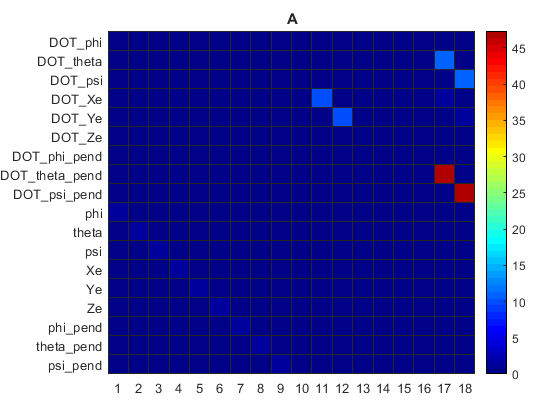

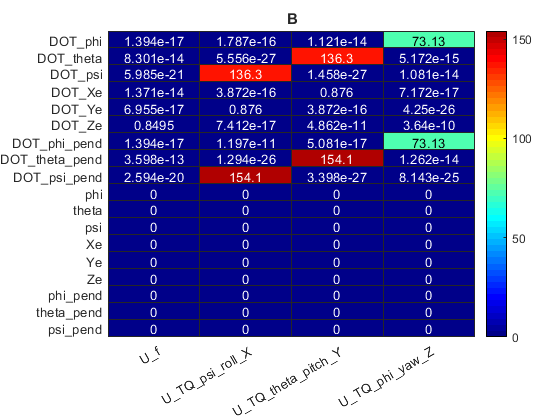

LOC_plot_scales(my_LIN_PLANT)

Apply a tolerence MASK

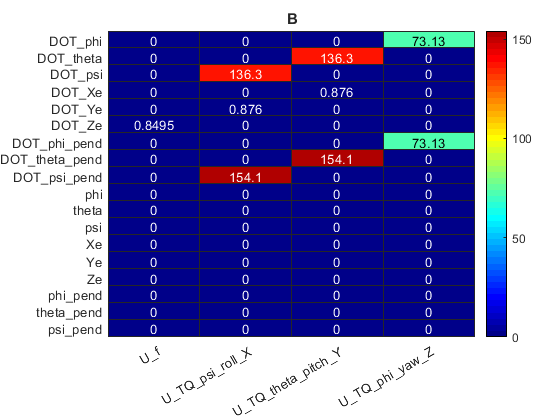

new_p = LOC_apply_mask(my_LIN_PLANT, 1e-9, 1e-9);

LOC_plot_scales(new_p)

Can we control

rank(  ctrb(new_p)  )

ans = 14

What about when we reduce

rank(  ctrb(minreal(new_p))  )

2 states removed.


ans = 14

# Local Subfunctions ONLY beyond this point

function LOC_plot_scales(my_p)


[A,B,C,D] = deal(my_p.A, my_p.B, my_p.C, my_p.D);

[A,B,C,D] = deal(abs(A), abs(B), abs(C), abs(D) );

NEARLY_ZERO = 0; %1e-50;

tf_mat = A ==0;  A(tf_mat) = NEARLY_ZERO;
tf_mat = B ==0;  B(tf_mat) = NEARLY_ZERO;
tf_mat = C ==0;  C(tf_mat) = NEARLY_ZERO;

%[A,B,C] = deal( log10(A), log10(B), log10(C) );

% tiledlayout(2,1);
% nexttile;

figure;
my_row_labels = strrep(my_p.StateName, '_', '\_');
heatmap(A, "Colormap",jet(50),"YDisplayLabels",my_row_labels);
title("A");

%nexttile;
figure;
my_col_labels = strrep(my_p.InputName, '_', '\_');
heatmap(B, "Colormap",jet(50),"YDisplayLabels",my_row_labels, ...
                              "XDisplayLabels",my_col_labels   );
title("B")
% nexttile;
% heatmap(C, "Colormap",jet(50));


end

Create a NEW A,B,C,D

function new_p = LOC_apply_mask(my_p, A_tol, B_tol)

[A,B,C,D] = deal(my_p.A, my_p.B, my_p.C, my_p.D);

[A,B,C,D] = deal(abs(A), abs(B), abs(C), abs(D) );

NEARLY_ZERO = 0; %1e-50;

tf_A_mat = A < A_tol;
tf_B_mat = B < B_tol;

new_p = my_p;

new_p.A(tf_A_mat) = 0;
new_p.B(tf_B_mat) = 0;


end